# Supermercados vs Aeropuertos

t = 0:0.1:10

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y=t.*sin(t)

y =          0    0.0100    0.0397    0.0887    0.1558    0.2397    0.3388    0.4510    0.5739    0.7050    0.8415    0.9803    1.1184    1.2526    1.3796    1.4962    1.5993    1.6858    1.7529    1.7980    1.8186    1.8127    1.7787    1.7151    1.6211    1.4962    1.3403    1.1539    0.9380    0.6938    0.4234    0.1289   -0.1868   -0.5206   -0.8688   -1.2277   -1.5931   -1.9604   -2.3251   -2.6823   -3.0272   -3.3549   -3.6606   -3.9395   -4.1870   -4.3989   -4.5710   -4.6996   -4.7816   -4.8140


funcion = y'

funcion =          0
    0.0100
    0.0397
    0.0887
    0.1558
    0.2397
    0.3388
    0.4510
    0.5739
    0.7050


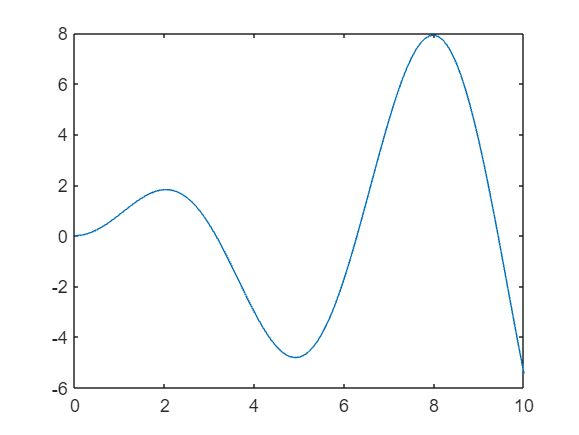

save('MS10Mensajes','funcion')
plot(t,y)

## Planteamiento del problema

¿Ha estado alguna vez en la caja de un supermercado y se ha preguntado por qué está en la cola más lenta? Aquí se presenta un ejemplo de cómo se pueden modelar los sistemas de colas en SimEvents para este tipo de aplicaciones. Se presentan dos versiones paralelas de un modelo simple de una caja de supermercado de cuatro registros: una que utiliza cuatro colas separadas y otra con una única cola "culebra" que alimenta todos los registros.

Para empezar, modelamos los clientes aleatorios que entran en la zona de cajas utilizando entidades para representar a los clientes que pueden generarse en intervalos de tiempo aleatorios siguiendo una distribución exponencial. Durante la generación especificamos una duración aleatoria (también distribuida exponencialmente) que un cliente tardará en ser atendido en una caja registradora asignando un atributo especial a la entidad correspondiente. El tiempo medio de servicio se fija en 2 minutos y el tiempo medio de llegada se fija en 1 minuto. Cada cliente se clona después de la generación para que las dos configuraciones de línea diferentes puedan ejercerse de forma idéntica.